## **Digital Communication Systems Laboratory**

## **Laboratory 04**

### **Section 01**

The initial parameters are usually defined at the beginning of the program.

clc; clear;
%TUID=915614617
A = 8;              % Signal amplitude
rb = 2000;          % Fundamental frequency of signal
Tb = 1 / rb;        % Period of signal
fs = 1000 * rb;     % Sampling frequency
Ts = 1 / fs;        % Sampling period

### Section 02

#### **Waveform Encodings**

If a waveform is assigned to a symbol, then the waveform can be transmitted instead of the symbol. This approach improves the detection process.

Suppose sinasoids are assigned to symbols:


$$s\left(t\right)=A\;\mathrm{sin}\left(\;2\pi \;f\;t+\phi \;\right)$$


If the message is embedded in the amplitude A, the encoding is called Amplitude Shift Keying (ASK).

If the message is embedded in the frequency *f*, the encoding is called Frequency Shift Keying (FSK).

If the message is embedded in the phase $\phi$, the encoding is called Phase Shift Keying (PSK).

### Section 03

#### Amplitude Shift Keying (ASK)

Suppose there are 4 symbols in the symbol set. Therefore, at least 4 bits are needed to encode the symbols in binary format.

M = 4;                  % Number of symbols
Nb = ceil(log2(M));     % Number of bits per symbol

In ASK encoding, the amplitude will carry the information. So, the amplitude of the sinosoid will be changed by the symbols.

For example:


$$\begin{array}{l}
\mathrm{Symbol}\;0:\;\mathrm{Amplitude}=-A\\
\mathrm{Symbol}\;1:\mathrm{Amplitude}=-\frac{A}{2}\\
\mathrm{Symbol}\;2:\mathrm{Amplitude}=+\frac{A}{2}\\
\mathrm{Symbol}\;3:\mathrm{Amplitude}=+A
\end{array}$$


This symbol sets can be shown in the original indices and the ASK encoded format:

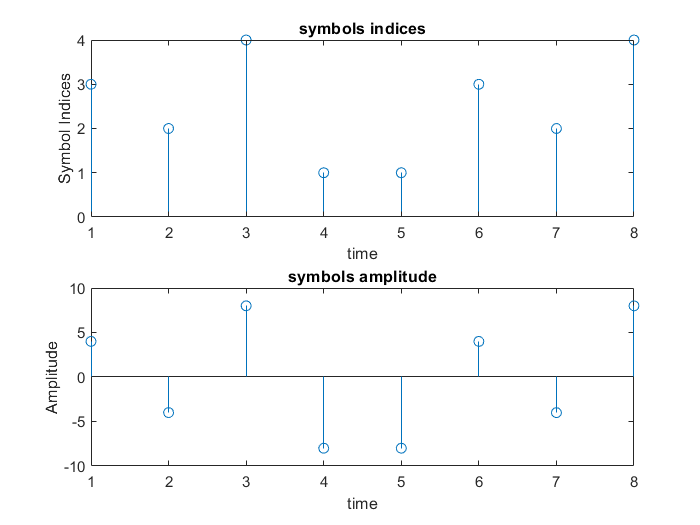

symbol_set = [1, 2, 3, 4];                          % symbols' indices
symbol_amplitude = [-A, -A/2, +A/2, +A];            % symbols' amplitude
msg = [3, 2, 4, 1, 1, 3, 2, 4];                     % message: a set of symbols
msg_amplitude = symbol_amplitude(symbol_set(msg));  % mepping the symbol to the amplitude
figure()
subplot(2, 1, 1); stem(msg); xlabel('time'); ylabel('Symbol Indices'); title('symbols indices');
subplot(2, 1, 2); stem(msg_amplitude); xlabel('time'); ylabel('Amplitude'); title('symbols amplitude');

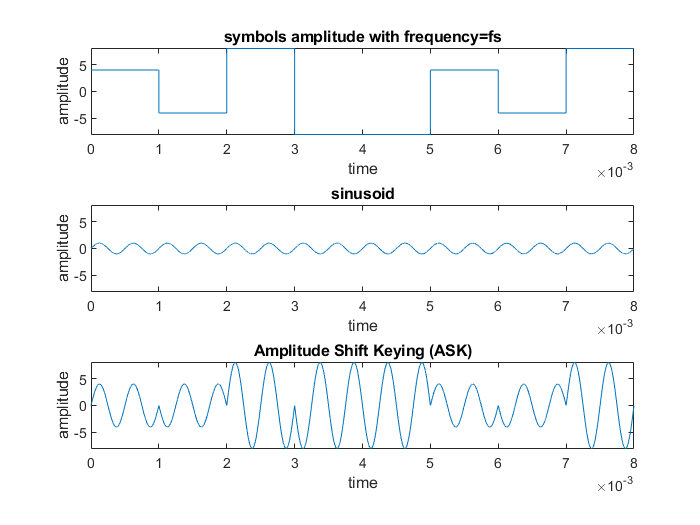

amplitudes = rate_transition(msg_amplitude, 1, rb);
t = (0:length(amplitudes)-1)*Ts;
sin_signal = 1 * sin(2 * pi * rb * t + 0);
signal = amplitudes .* sin_signal;
figure()
subplot(3, 1, 1); plot(t, amplitudes); xlabel('time'); ylabel('amplitude'); ylim([-A-0.1, +A+0.1]); title('symbols amplitude with frequency=fs')
subplot(3, 1, 2); plot(t, sin_signal); xlabel('time'); ylabel('amplitude'); ylim([-A-0.1, +A+0.1]); title('sinusoid');
subplot(3, 1, 3); plot(t, signal); xlabel('time'); ylabel('amplitude'); ylim([-A-0.1, +A+0.1]); title('Amplitude Shift Keying (ASK)');

### Section 04

#### Decoding and Detection

Decoding tries to find the indices of transmitted symbols.

Detection means to find the message that has been transmitted.

There are several methods to decode the received signal, but the correlation decoder is the most common. The matched filter is an LTI implementation of correlator, so both are the same with different formulation.

If the received signal is $r\left(t\right)$ and the base encoding signal is $s\left(t\right)$ then correlator decoder works as follow:


$$a=\int_0^{T_s } r\left(t\right)s\left(t\right)\mathrm{dt}$$


The detection will be done with coefficient $a$, for example with a threshold.

If we have several base encoding signal ($s_i \left(t\right)$) then several coefficients will be computed as follow:


$$a_i =\int_0^{T_s } r\left(t\right)s_i \left(t\right)\mathrm{dt}$$


Then detection will be done with all coefficiens $\left\lbrace a_1 ,a_2 ,\;\ldotp \ldotp \ldotp ,a_m \right\rbrace$

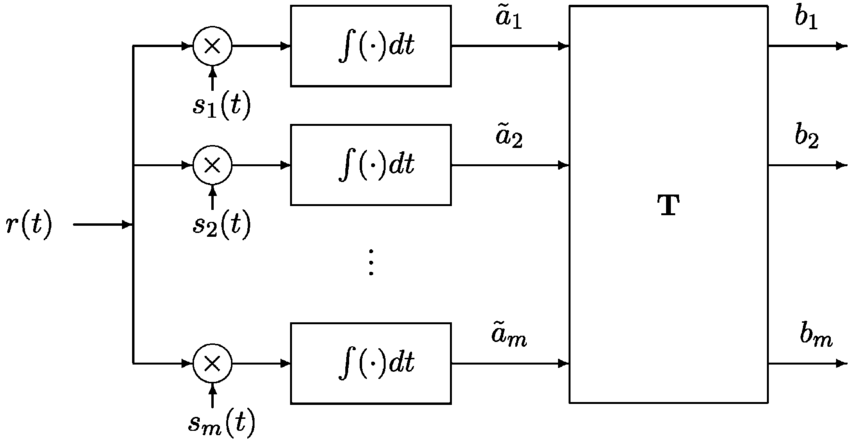

### Section 05

#### ASK Correlator Decoder and Detection

Since only a single sinusoid has used for encoding, a single correlator will be enough for detection.


$$a=\int_0^{T_s } r\left(t\right)\mathrm{sin}\left(2\pi \mathrm{ft}\right)\mathrm{dt}$$


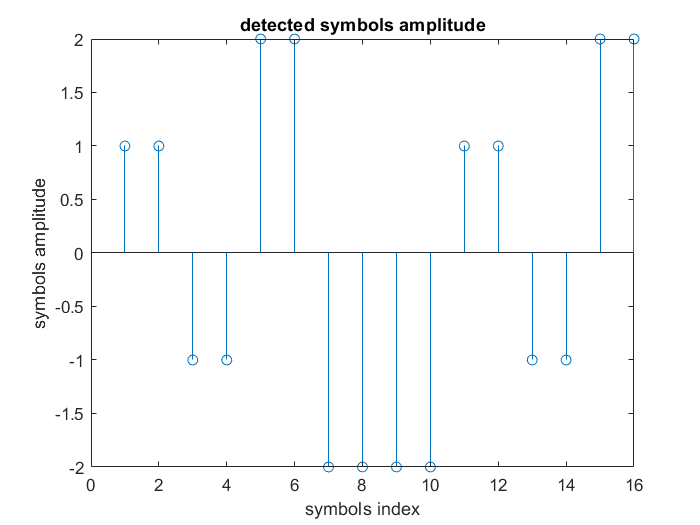

% decoding
rt = signal;
Ns = fs / rb;
dec_signal = zeros([1, floor(length(rt) * rb/fs)]);
dcounter = 1;
for n = Ns:Ns:length(rt)
    r_hat_t = rt(n-Ns+1:n) .* sin(2*pi*rb*(0:Ns-1)*Ts);
    dec_signal(dcounter) = sum(r_hat_t)*Tb;
    dcounter = dcounter + 1;
end
figure()
stem(dec_signal); xlabel('symbols index'); ylabel('symbols amplitude'); title('detected symbols amplitude');

% detection
% finding the unique levels
levels = [-inf, unique(round(dec_signal, 2)), inf]

levels =   -Inf    -2    -1     1     2   Inf


% finding the thresholds
thresholds = (levels(2:end) + levels(1:end-1))/2

thresholds =       -Inf   -1.5000         0    1.5000       Inf


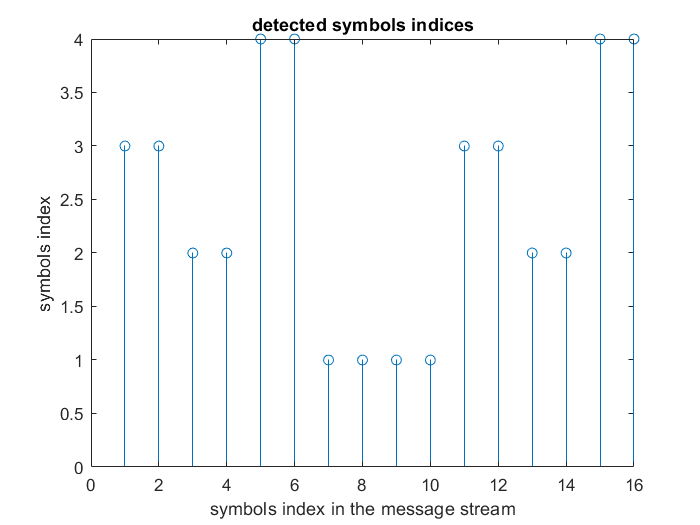

detected_indices = zeros([1, length(dec_signal)]);
for n = 1:length(dec_signal)
    lvl = sort([thresholds, dec_signal(n)]);
    indices = 1:length(lvl);
    detected_indices(n) = indices(lvl == dec_signal(n)) - 1;
end
figure()
stem(detected_indices); xlabel('symbols index in the message stream'); ylabel('symbols index'); title('detected symbols indices');

% computing error rates
err = mean(abs(msg - detected_indices))

Matrix dimensions must agree.

### Section 06

#### Noise

Noise is the impact of channel that signal transfer through.

The most common way to find the noise impact is Additive White Gaussian Noise (AWGN) model. In this model, the noise will be generted by a Gaussian distribution and added to the transmitted signal.

% generation of a random message with fixed length
rng(0);
Nm = 10;
symbol_set = [1, 2, 3, 4];                          % symbols' indices
symbol_amplitude = [-A, -A/2, +A/2, +A];            % symbols' amplitude
msg = randi(M, [1, Nm]);                            % message: a set of symbols
figure(); stem(msg);
msg_amplitude = symbol_amplitude(symbol_set(msg));  % mepping the symbol to the amplitude
amplitudes = rate_transition(msg_amplitude, 1, rb); % translate rate 1 to rate rb
t = (0:length(amplitudes)-1)*Ts;                    % make the parameter time
sin_signal = 1 * sin(2 * pi * rb * t + 0);          % simple sinusoid wave
signal = amplitudes .* sin_signal;                  % message multiply by sinusoid
figure(); plot(signal);
%change snr, chart error
snr = 10;
noisy_signal = awgn(signal, snr, 'measured');
figure(); plot(noisy_signal);
% decoding
rt = noisy_signal;
Ns = fs / rb;
dec_signal = zeros([1, floor(length(rt) * rb/fs)]);
dcounter = 1;
for n = Ns:Ns:length(rt)
    r_hat_t = rt(n-Ns+1:n) .* sin(2*pi*rb*(0:Ns-1)*Ts);
    dec_signal(dcounter) = sum(r_hat_t)*Tb;
    dcounter = dcounter + 1;
end
% detection
detected_indices = zeros([1, length(dec_signal)]);
for n = 1:length(dec_signal)
    lvl = sort([thresholds, dec_signal(n)]);
    indices = 1:length(lvl);
    detected_indices(n) = indices(lvl == dec_signal(n)) - 1;
end
figure(); stem(detected_indices);
% computing error rates
err = mean(abs(msg - detected_indices))

### Functions Definition

Rate transition:

function rt = rate_transition(s, f1, f2)
    if (f1 < f2)
        rt = repelem(s, floor(f2/f1));
    else
        step = floor(f1/f2);
        rt = s(1:step:end);
    end
end